generazione report

import mlreportgen.report.*;
import mlreportgen.dom.*;

doctype = "pdf";
rpt = Report("Risultati",doctype);

create title page

tp = TitlePage("Title","Ageing project","Subtitle","Results");
add(rpt,tp);

Create chapter 1 and section 1

% ch1 = Chapter("Title");
% s1 = Section("blablabla");
% p1 = Text(" "); % qui scriviamo un breve pezzo di commenti su cosa vedremo

esempio su project Num. Analysis

% Subject 1

% a1 = 16;    % forget rate
% b1 = 5;     % rate of responsiveness to partner's affection
% c1 = 1;     % rate of reactivity to partner's charms
% F1 = 30;    % charm
% 
% % Subject 2
% a2 = 8;     % forget rate
% b2 = 10;    % rate of responsiveness to partner's affection
% c2 = 1;     % rate of reactivity to partner's charms
% F2 = 60;    % charm
% 
% love = @(t,x) [-a1*x(1)+b1*x(2)+c1*F2; -a2*x(2)+b2*x(1)+c2*F1];
% 
% tstart = 0;
% tfinal = 3;
% tspan = [tstart tfinal];
% 
% x0 = [20,10];
% [t,x] = ode45(@(t,x) love(t,x),tspan,x0);
% figure(1)
% plot(t,x')
% title('System behavior for initial values [20 10]');
% legend('x1','x2')
% grid on

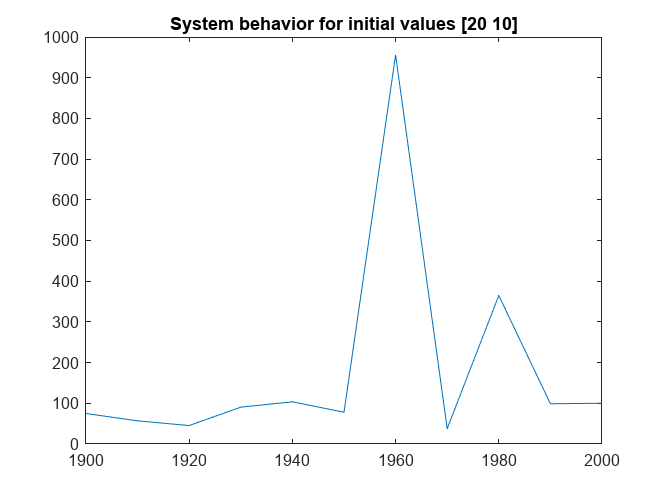

ch1 = Chapter("Title");
s1 = Section("blablabla");
p1 = Text(" "); % qui scriviamo un breve pezzo di commenti su cosa vedremo

t = (1900:10:2000)';
p = [75.000 56.899 45.378 90.534 103.678 78,956 37.890 364.908 98.903 100.100]';
fig_1 = Figure(plot(t,p));
% axis([]);
title("System behavior for initial values [20 10]"); % title of the figure

%xlabel or ylabel

add(s1,p1);
add(s1,fig_1);
add(ch1,s1);

Create section 2 chapter 1

% s2 = Section("Title");
% p1 = ("");
% p2 = ("");
% 
% % c(:,1) = % tabella da analizzare
% % c(:,2) = % seconda riga tabella da analizzare
% 
% % tbl = BaseTable(c);
% % tbl.TableWidth = "5in";
% % tbl.Title = "";
% 
% add(s2,p1);
% add(s2,p2);
% % add(s2,tbl);
% add(ch1,s2);
% add(rpt,ch1);

close and view the report

close(rpt);
rptview(rpt);